# Tuning the crazyflie drone

The desired overshoot is set to 2% and 

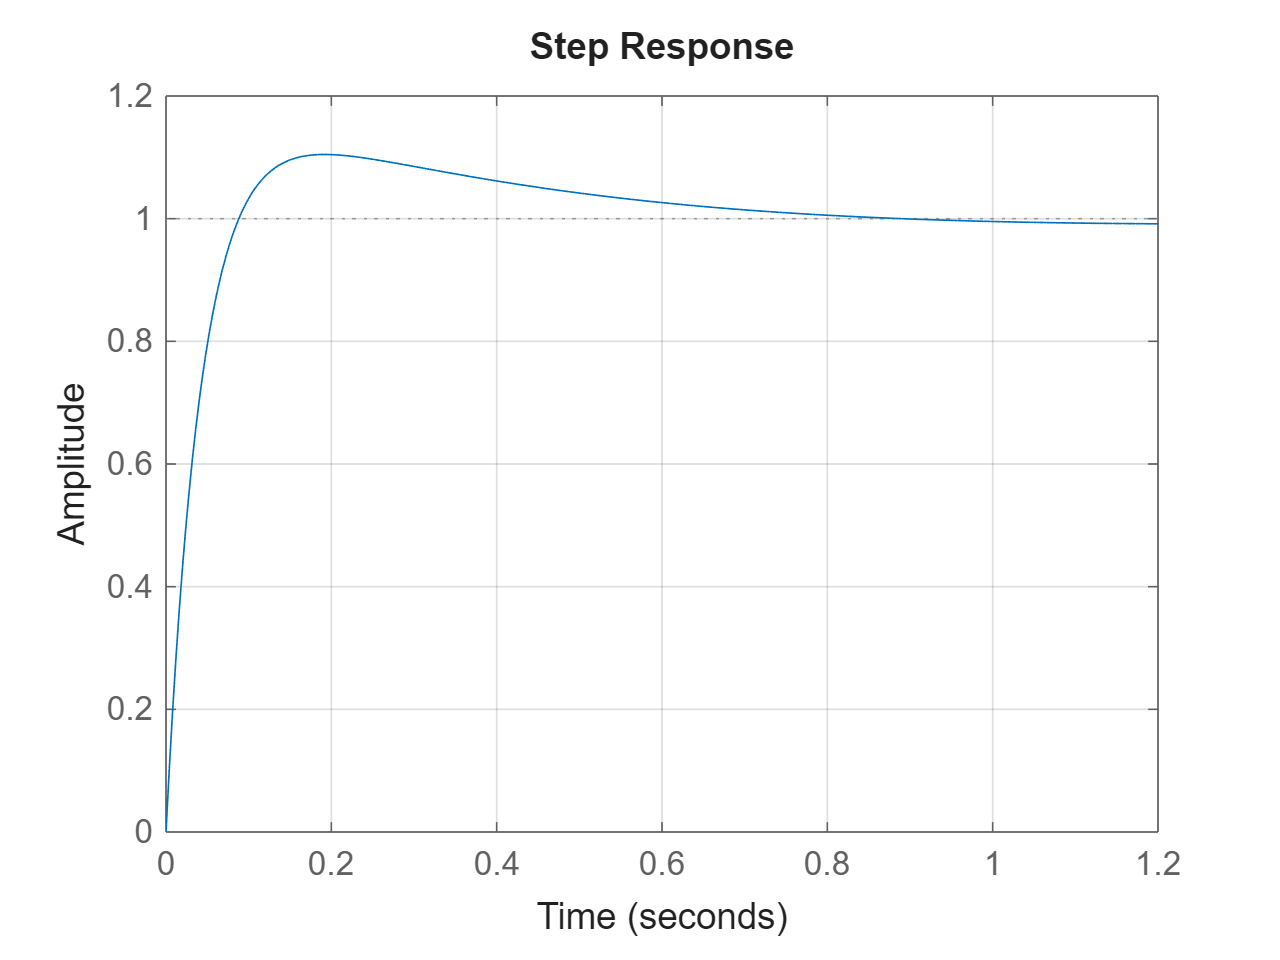

%creating a controller tuning with P.O. < 2%
P_O = 2; %percentage overshoot
t_s = 2; %settling time

Mp  = P_O/100;
zeta = -log(Mp) / sqrt(pi^2 + log(Mp)^2);

wn  = 4/(zeta*t_s);

alpha = 9;     
p = alpha*wn;

m = 27e-3;

Kd = m*(p + 2*zeta*wn);
Kp = m*(2*p*zeta*wn + wn^2);
Ki = m*(p*wn^2);

s = tf('s');
G = 1/(m*s^2);
C = Kp + Ki/s + Kd*s;
T = feedback(C*G,1);

step(T); grid on;

stepinfo(T)

ans = struct with fields:
         RiseTime: 0.0613
    TransientTime: 0.6487
     SettlingTime: 0.6487
      SettlingMin: 0.9149
      SettlingMax: 1.1047
        Overshoot: 10.4653
       Undershoot: 0
             Peak: 1.1047
         PeakTime: 0.1915



fprintf('Kd:%.3f, Kp:%.3f, Ki:%.3f', Kd, Kp, Ki);

Kd:0.731, Kp:2.671, Ki:4.101

Using the RL method

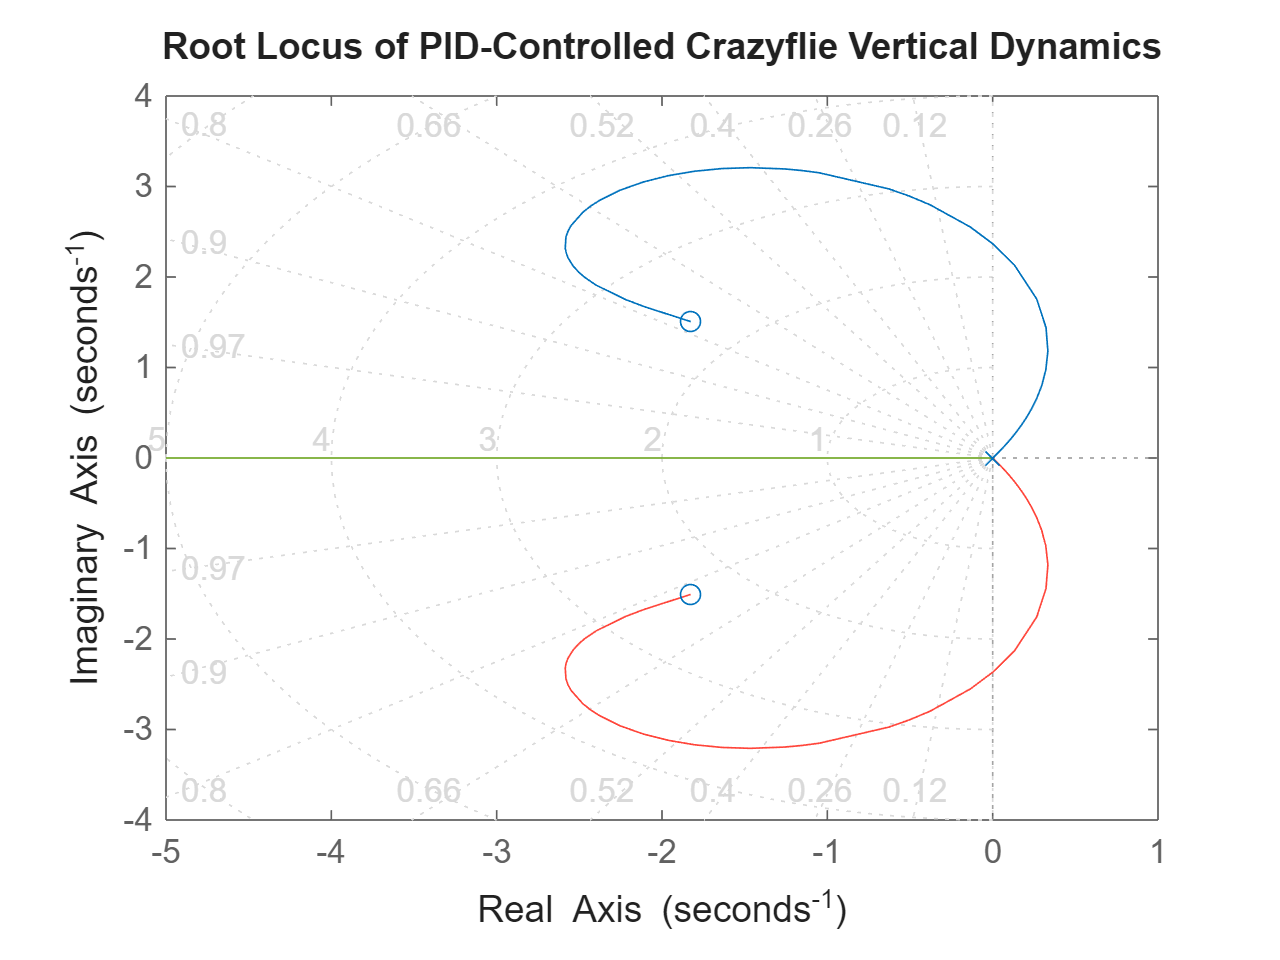

% Open-loop plant
G = 1/(m*s^2);

% PID WITHOUT embedding gain into C(s)
C0 = Kd*s + Kp + Ki/s;

% Define L0(s) for root locus: L(s) = K * L0(s)
L0 = C0 * G;

figure;
rlocus(L0);
title('Root Locus of PID-Controlled Crazyflie Vertical Dynamics');
grid on;